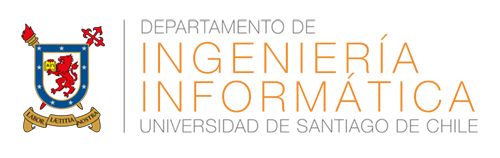

# Tarea N° 3

## PROCESAMIENTO DE SEÑALES E IMÁGENES

### Estudiante: Jaime Riquelme Olguin - 20964708-7

## Conceptos y Fórmulas

### Puntos Clave del Proceso

En el proceso, tuve en cuenta dos factores principales que se nos entregan: 

- El ángulo azimutal θ (theta), que representa la dirección horizontal del sonido.

- El ángulo de elevación ϕ (phi), que representa la dirección vertical del sonido (en este caso es 0)

### Fórmula de Interpolación HRIR

Se creó una salida estéreo espacializada a partir de una señal de entrada mono x(n), usando el siguiente sistema:

- 
$$y_l (n) = x(n) \ast h^{\theta \phi}_l (n)$$


- 
$$y_r (n) = x(n) \ast h^{\theta \phi}_r (n)$$


Donde:

- $y_l(n)$ y $y_r(n)
$ son las salidas de los canales izquierdo y derecho

- * denota convolución

- $h_l

$ y $h_r
$ son las HRIR izquierda y derecha para los ángulos deseados

### Segmentación de Señal y Crossfade

Para crear el efecto de sonido en movimiento, realicé los siguientes pasos:

- Dividí la señal de entrada en 24 partes iguales. Cada parte dura 1 segundo y tiene 500 muestras de superposición con la siguiente.

- Convolucione cada segmento con HRIRs correspondientes a diferentes ángulos azimutales. Esto simula el sonido viniendo de diferentes direcciones.

- Apliqué el crossfade entre segmentos consecutivos en las regiones de superposición. Esto crea transiciones suaves entre los segmentos.

- Combiné todos los segmentos procesados en una única señal de salida estéreo continua.

**Fórmula de crossfade: salida = fade_out * segmento1 + fade_in * segmento2**

Donde fade_out y fade_in son rampas lineales entre 0 y 1.

## codigo

% cargo las respuestas del impulso del archivo
load('IRC_1002_R_HRIR.mat');

% cargo el archivo de audio
[audio, Fs] = audioread('helicopter.wav');

% configuro los parámetros
ang_azim = 0:15:345; % angulos en grados
long_seg = Fs; % duración de cada segmento en muestras (1 segundo)
superp = 500; % número de muestras de traslape entre segmentos
num_seg = 24; % número de segmentos

% divido el audio en segmentos con traslape
segmentos = zeros(long_seg + superp, num_seg);
for i = 1:num_seg
    ini = (i-1) * (long_seg - superp) + 1;
    fin = min(ini + long_seg + superp - 1, length(audio));
    segmentos(:, i) = [audio(ini:fin); zeros(long_seg + superp - (fin-ini+1), 1)];
end

% inicializo las señales de salida
sal_izq = zeros(length(audio) + (num_seg-1) * superp, 1);
sal_der = zeros(length(audio) + (num_seg-1) * superp, 1);

% creo rampas de fade in y fade out
fade_in = linspace(0, 1, superp)';
fade_out = linspace(1, 0, superp)';

% proceso cada segmento con las HRIRs
for i = 1:num_seg
    ang = ang_azim(mod(i-1, length(ang_azim)) + 1);
    idx = ang / 15 + 1;

    % obtengo las respuestas al impulso para el ángulo seleccionado
    hrir_izq = l_hrir_S.content_m(idx, :);
    hrir_der = r_hrir_S.content_m(idx, :);

    % convoluciono el segmento con las respuestas al impulso
    conv_izq = conv(segmentos(:, i), hrir_izq, 'full');
    conv_der = conv(segmentos(:, i), hrir_der, 'full');

    % determino los indices de inicio y fin para sumar el segmento convolucionado
    ini = (i-1) * (long_seg - superp) + 1;
    fin = ini + length(conv_izq) - 1;
    if i > 1
        % aplico crossfade para los segmentos siguientes
        ini_sup = ini;
        fin_sup = ini + superp - 1;
        sal_izq(ini_sup:fin_sup) = sal_izq(ini_sup:fin_sup) .* fade_out + conv_izq(1:superp) .* fade_in;
        sal_der(ini_sup:fin_sup) = sal_der(ini_sup:fin_sup) .* fade_out + conv_der(1:superp) .* fade_in;
        sal_izq(fin_sup+1:fin) = conv_izq(superp+1:end);
        sal_der(fin_sup+1:fin) = conv_der(superp+1:end);
    else
        % para el primer segmento, no necesito aplicar crossfade
        sal_izq(ini:fin) = conv_izq;
        sal_der(ini:fin) = conv_der;
    end
end

%guardo el resultado
sal_stereo = [sal_izq, sal_der];
audiowrite('sal_heli.wav', sal_stereo, Fs);



### Parametros Clave dentro del Codigo:

- Longitud de segmento: 1 segundo.

- Superposición: 500 muestras entre segmentos consecutivos.

- Ángulos azimutales: 0° a 345° en incrementos de 15°.

### Gráficos de los audios

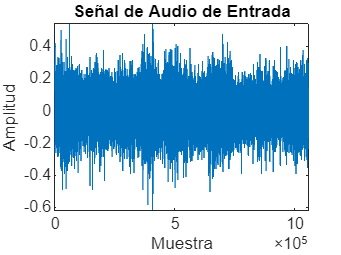

% visualizar señal de entrada
figure;
plot(audio);
title('Señal de Audio de Entrada');
xlabel('Muestra');
ylabel('Amplitud');

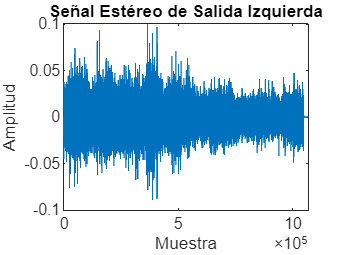


% visualizar señal de salida individual
figure;
plot(sal_izq);
title('Señal Estéreo de Salida Izquierda');
xlabel('Muestra');
ylabel('Amplitud');

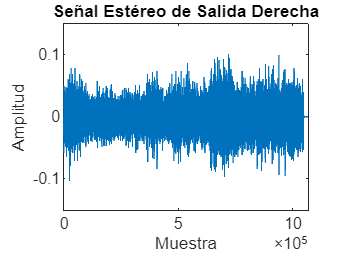


figure;
plot(sal_der);
title('Señal Estéreo de Salida Derecha');
xlabel('Muestra');
ylabel('Amplitud');

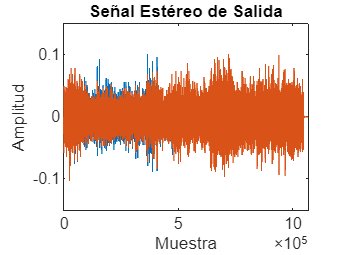


% visualizar señal de salida final
figure;
plot(sal_stereo);
title('Señal Estéreo de Salida');
xlabel('Muestra');
ylabel('Amplitud');

### Resultados

El archivo resultante `sal_heli.wav` crea un efecto de audio 3D donde el sonido del helicóptero parece moverse alrededor Este efecto se logró mediante:

- Uso de diferentes HRIR para cada segmento, simulando sonido desde diferentes direcciones

- Transiciones suaves entre segmentos usando la técnica de crossfade

- Procesamiento separado para los canales izquierdo y derecho para crear un efecto estéreo

- Unión de los canales izquierdo y derecho en un solo audio de salida estéreo